clear;close all
h=1;
m=1;
a=1;

function E=Energy(n)
h=1;
m=1;
a=1;
E=n.^2*pi^2*h^2/(2*m*a^2);
end
%a

for N=1:3
    dx=a/(N+1);
    lambda=h^2/(2*m*dx^2);
    H=lambda*(2*eye(N)-diag(ones(N-1,1),1)-diag(ones(N-1,1),-1))
   %eye(N) is identity size NxN
end

H = 4

H =     9.0000   -4.5000
   -4.5000    9.0000


H =     16    -8     0
    -8    16    -8
     0    -8    16



%B
%eigenvalues vs exact
for N=1:3
    dx=a/(N+1);
    lambda=h^2/(2*m*dx^2);
    H=lambda*(2*eye(N)-diag(ones(N-1,1),1)-diag(ones(N-1,1),-1));
    disp(N)
    Enum=sort(eig(H))
    Eex=Energy(1:N)'
    %comparing
    
    (Eex-Enum).*100 ./ Eex
end

     1



Enum = 4

Eex = 4.9348

ans = 18.9431

     2



Enum =     4.5000
   13.5000


Eex =     4.9348
   19.7392


ans =     8.8109
   31.6082


     3



Enum =     4.6863
   16.0000
   27.3137


Eex =     4.9348
   19.7392
   44.4132


ans =     5.0359
   18.9431
   38.5009



%C
%five lowest eigenvalues for N=10 and N=100
for N=[10,100]
    dx=a/(N+1);
    lambda=h^2/(2*m*dx^2);
    H=lambda*(2*speye(N)-spdiags(ones(N,1),1,N,N)-spdiags(ones(N,1),-1,N,N));
    Enum=sort(eig(full(H)));
    disp(N)
    Enum=Enum(1:5)
    Eex=Energy(1:5)'
end

    10



Enum =     4.9014
   19.2083
   41.7619
   70.7348
  103.7799


Eex =     4.9348
   19.7392
   44.4132
   78.9568
  123.3701


   100



Enum =     4.9344
   19.7328
   44.3810
   78.8550
  123.1216


Eex =     4.9348
   19.7392
   44.4132
   78.9568
  123.3701


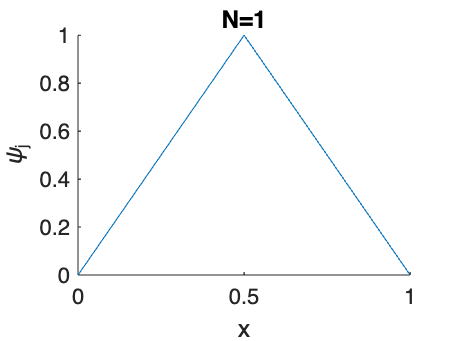

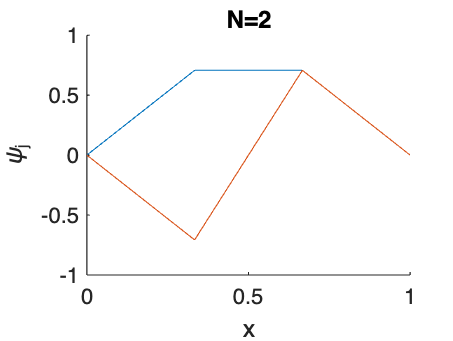

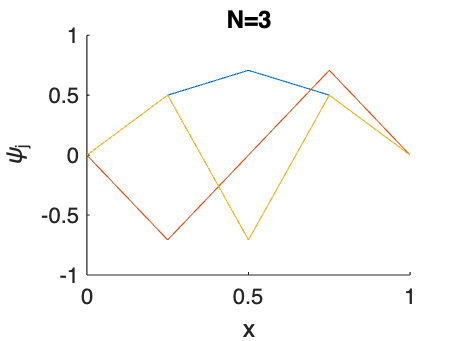

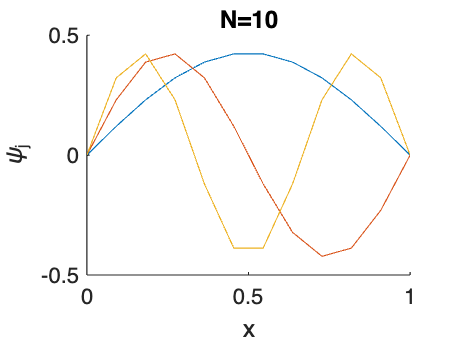

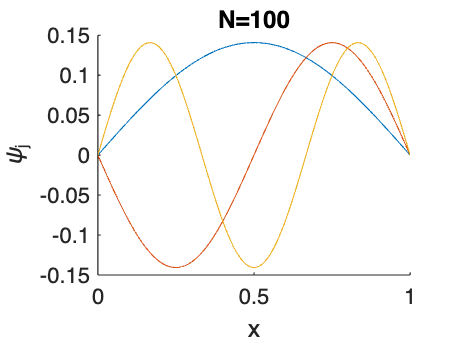


%D

Nplotvals=[1,2,3,10,100];

for k=1:5
    N=Nplotvals(k);
    dx=a/(N+1);
    lambda=h^2/(2*m*dx^2);
    H=lambda*(2*eye(N)-diag(ones(N-1,1),1)-diag(ones(N-1,1),-1));
    [V,E]=eig(H);
    [~,order]=sort(diag(E));
    V=V(:,order);
    x=(0:N+1)*dx;
    figure
    hold on
    %disp(sign(V(:,1))) %IDK why the ground state is flipping signs
    if (sign(V(1,1))) == -1
        V(:,1)=-V(:,1);%very physics based fix
    end
    for n=1:min(3,N)
        plot(x,[0;V(:,n);0])
    end
    title(['N=',num2str(N)])
    xlabel('x')
    ylabel('\psi_j')
end


%blue is ground state red is first excited and yellow is 2nd excited
